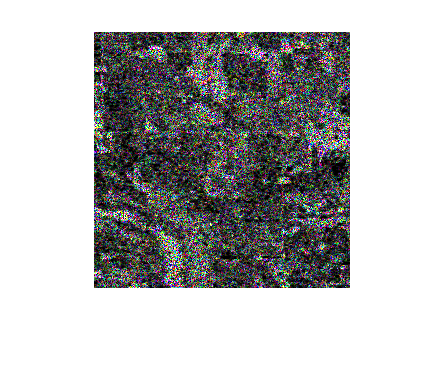

input = imread("Noisy_dataset/noise66.png");
Inoise = im2double(input);
imshow(Inoise);

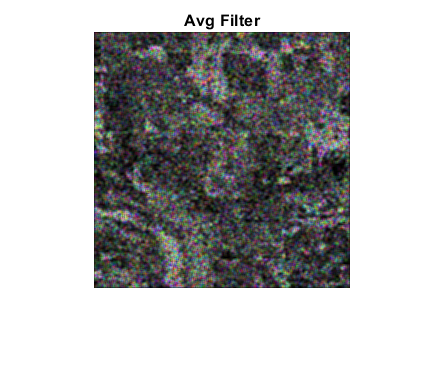

output_avg = Avgfilter(Inoise,3,3);
output_med = medfilt3(Inoise,[3,3,5]);
output_gaus = imgaussfilt3(Inoise,0.5);
figure;
subplot(1,1,1);
imshow(output_avg);
title("Avg Filter");

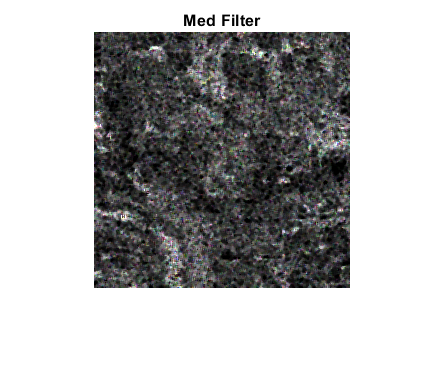

figure;
subplot(1,1,1);
imshow(output_med);
title("Med Filter");

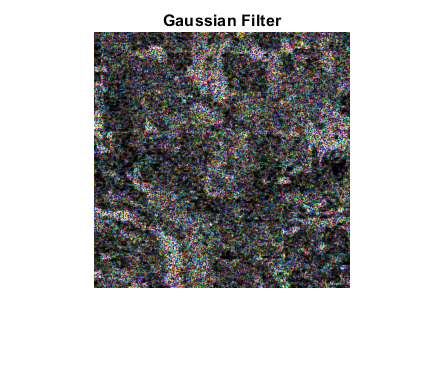

figure;
subplot(1,1,1);
imshow(output_gaus);
title("Gaussian Filter");

function Avg_out = Avgfilter(img,kernel_h,kernel_w)

    Avg_in = fspecial('average',[kernel_h,kernel_w]);
    Avg_out = imfilter(img,Avg_in);
    
end


